# K-means clustering

clear;clc;

## Data Processing

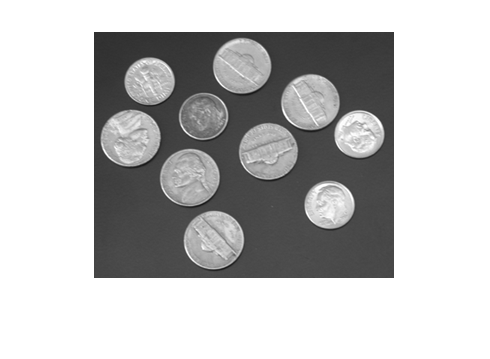

coins = imread('coins.png');
imshow(coins);

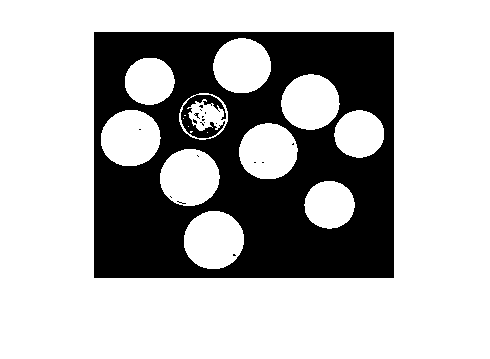

level = graythresh(coins);
coins = imbinarize(coins,level);
imshow(coins);

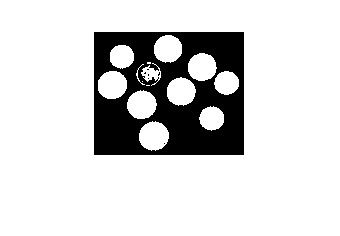

coins = imresize(coins, [round(size(coins,1)/2), round(size(coins,2)/2)]);
imshow(coins);

X_train = zeros(size(coins,1)*size(coins,2),3);
k = 1;
for i=1:size(coins,1)
    for j=1:size(coins,2)
        X_train(k,:) = [i j coins(i,j)*255];
        k = k+1;
    end
end

## Image Segmentation

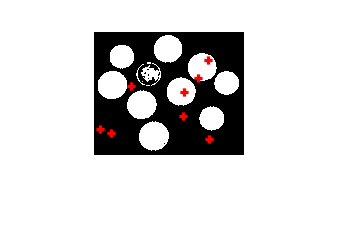

class_assign = zeros(size(X_train,1),1);
prev_class_assign = rand(size(X_train,1),1);
K = 8;
means = rand(K,size(X_train,2));
% shift = round(size(X_train,1)/K);
for i=1:K
    r = round(size(X_train,1)*rand(1,1));
    if r==0
        r = r+1;
    end
%     r = shift*i;    
    means(i,:) = X_train(r,:);
end

imshow(coins);
hold on;
for i=1:K
    plot(round(means(i,1)),round(means(i,2)), 'r+', 'MarkerSize', 5, 'LineWidth', 2);
end
hold off;

itr = 0;
max_itr = 50;
while sum(prev_class_assign==class_assign)<size(X_train,1)
    if itr>max_itr
        break;
    end
    itr = itr + 1;
    disp(["Iteration " + num2str(itr)]);
    prev_class_assign = class_assign;
    J = zeros(K,1);
    for j=1:size(X_train,1)
        dists = zeros(K,1);
        for i=1:K
            dists(i,:) = norm(X_train(j,:)-means(i,:));
        end
        [dist,c] = min(dists);
        class_assign(j,:) = c;
        J(c) = J(c) + dist;
    end
    means = zeros(K,size(X_train,2));
    for j=1:size(X_train,1)
        for i=1:K
            if class_assign(j,:)==i
                means(i,:) = means(i,:) + X_train(j,:);
            end
        end
    end
    for i=1:K
        means(i,:) = means(i,:)/sum(class_assign==i);
    end
    disp("Cost J "+num2str(sum(J)));
end

Iteration 1


Cost J 644199.3707


Iteration 2


Cost J 489223.0264


Iteration 3


Cost J 456866.8585


Iteration 4


Cost J 443411.7764


Iteration 5


Cost J 440769.999


Iteration 6


Cost J 439925.0443


Iteration 7


Cost J 439245.5273


Iteration 8


Cost J 438661.3891


Iteration 9


Cost J 438247.2629


Iteration 10


Cost J 437940.678


Iteration 11


Cost J 437747.8636


Iteration 12


Cost J 437640.826


Iteration 13


Cost J 437556.958


Iteration 14


Cost J 437503.5343


Iteration 15


Cost J 437455.4029


Iteration 16


Cost J 437446.1652


Iteration 17


Cost J 437430.6777


Iteration 18


Cost J 437401.5289


Iteration 19


Cost J 437379.2136


Iteration 20


Cost J 437371.1232


Iteration 21


Cost J 437365.3366


Iteration 22


Cost J 437353.4794


Iteration 23


Cost J 437341.5547


Iteration 24


Cost J 437331.2449


Iteration 25


Cost J 437319.1088


Iteration 26


Cost J 437300.6327


Iteration 27


Cost J 437295.301


Iteration 28


Cost J 437282.5838


Iteration 29


Cost J 437264.161


Iteration 30


Cost J 437241.7799


Iteration 31


Cost J 437231.4453


Iteration 32


Cost J 437225.8511


Iteration 33


Cost J 437200.52


Iteration 34


Cost J 437193.4597


Iteration 35


Cost J 437192.4357


Iteration 36


Cost J 437179.4618


Iteration 37


Cost J 437183.8325


Iteration 38


Cost J 437176.4485


Iteration 39


Cost J 437177.6397


Iteration 40


Cost J 437173.4283


Iteration 41


Cost J 437172.1278


Iteration 42


Cost J 437156.5462


Iteration 43


Cost J 437147.7518


Iteration 44


Cost J 437145.3984


Iteration 45


Cost J 437137.14


Iteration 46


Cost J 437139.7235


Iteration 47


Cost J 437124.9001


Iteration 48


Cost J 437114.8336


Iteration 49


Cost J 437099.171


Iteration 50


Cost J 437085.7574


Iteration 51


Cost J 437074.3136


## Results

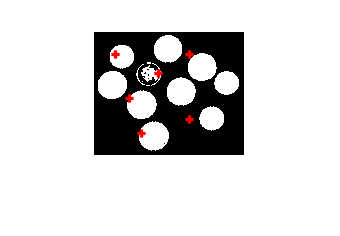

imshow(coins);
hold on;
for i=1:K
    plot(round(means(i,1)),round(means(i,2)), 'r+', 'MarkerSize', 5, 'LineWidth', 2);
end
hold off;